# This is the live script for ESE 6190 HW7 Explicit, Robust, & Hybrid MPC Exercise 1

clear all
clc

## Multiparametric Programming and Dynamic Programming

## dynamics, cost weight

A = [1 1;0 1];
B = [0; 1];
Q = [1 1; 0 1];
P = 0.8;
R = [1 1; 0 1];

## Solve the mp-LP for general controller, from end to start

for N = 1:4
    u = sdpvar(1, 1);
    x0 = sdpvar(2, 1);
    xp = A*x0 + B*u;
    if N == 1
        final_cost = norm(R*xp,inf);
    else
        for i = 1:optimizer.Num
            C = optimizer.Set(i).Functions('obj').F;
            d = optimizer.Set(i).Functions('obj').g;
            J_f(i) = C*xp + d;
        end
        final_cost = max(J_f);
    end
    J = final_cost + norm(Q*x0,inf) + norm(P*u,inf);
    if N == 1
        C = [ -10 <= x0 <= 10;
          -10 <= xp <= 10;
           -1 <= u  <= 1;];
    else
        C = [ -10 <= x0 <= 10;
                  Ex*xp <= fx;
               -1 <= u  <= 1;];
    end
    mpLP = Opt(C, J, x0, u);
    solution(N) = mpLP.solve();
    optimizer = solution(N).xopt;
    Ex = optimizer.Domain.A;
    fx = optimizer.Domain.b;
end

mpt_plcp: 16 regions
mpt_plcp: 34 regions
mpt_plcp: 63 regions
mpt_plcp: 92 regions


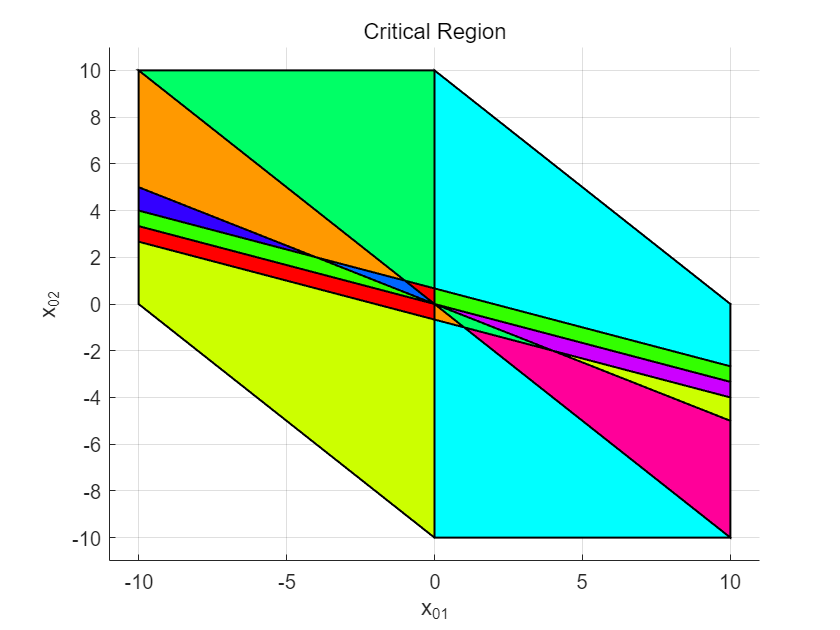

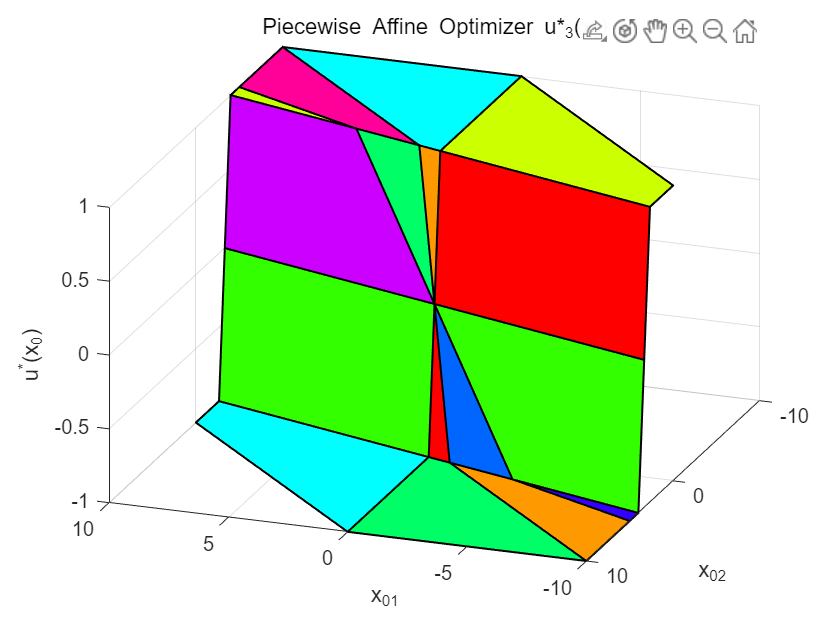

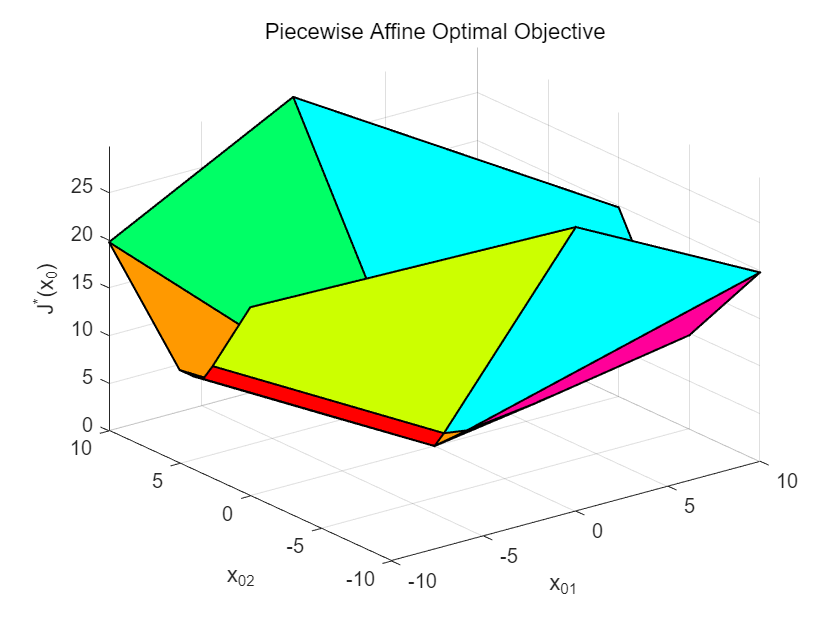

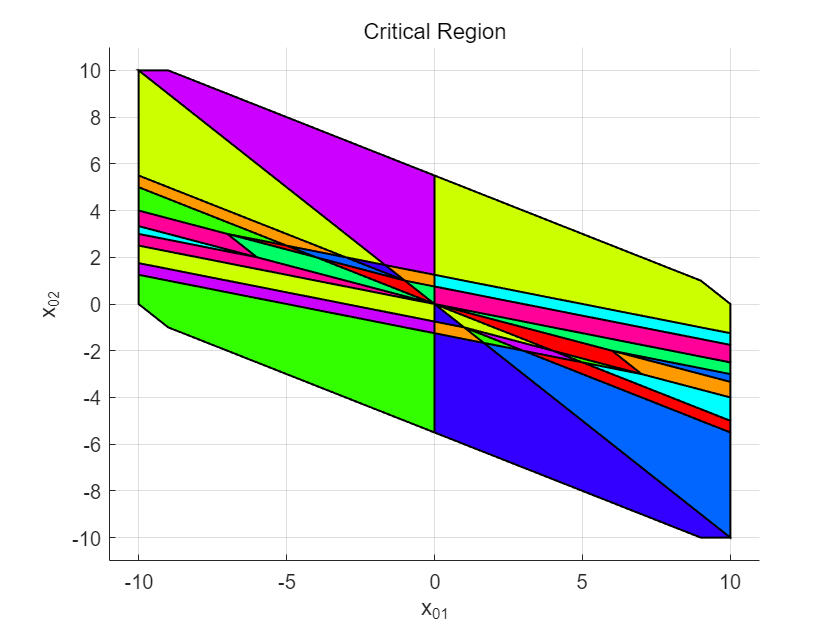

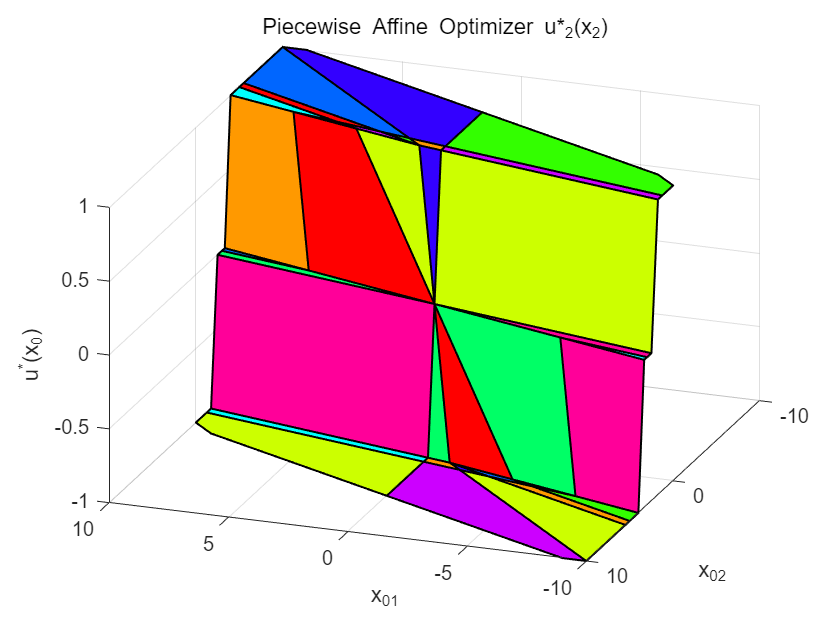

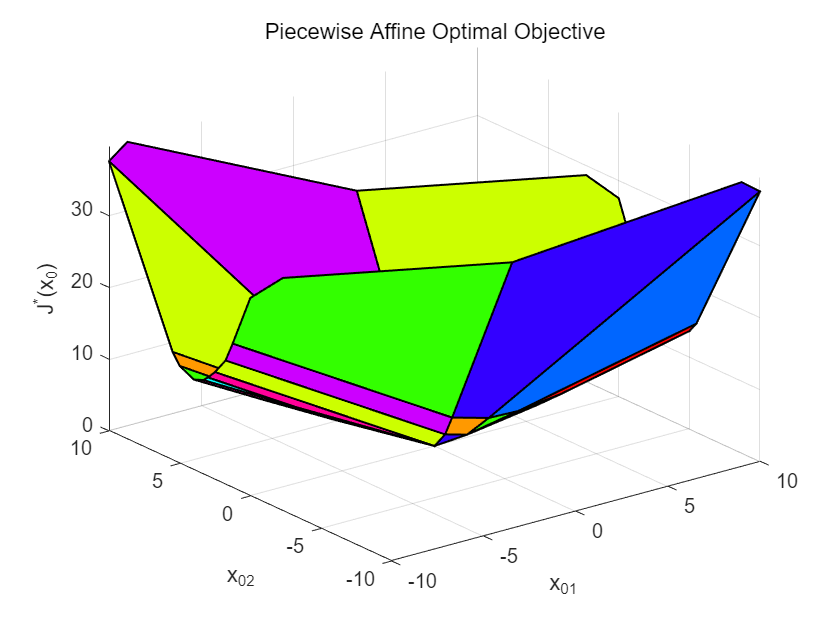

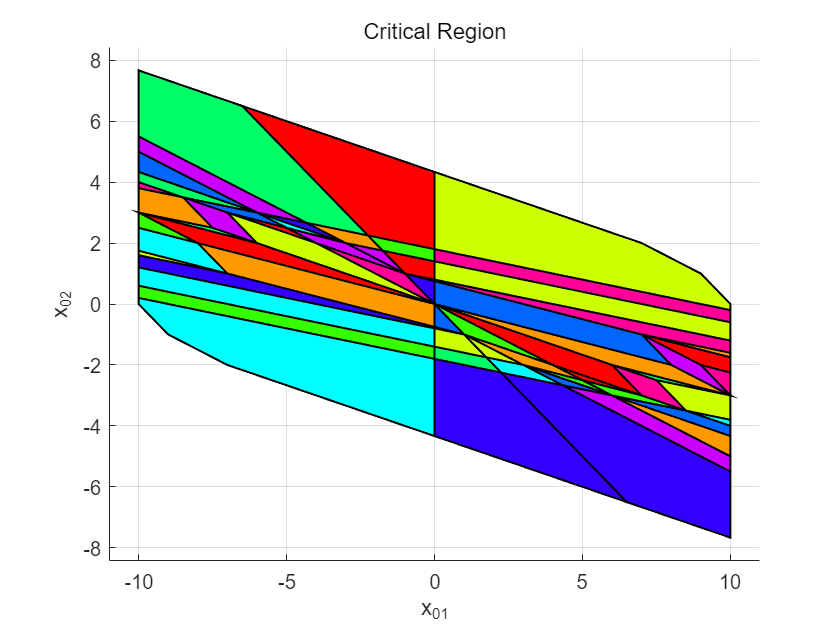

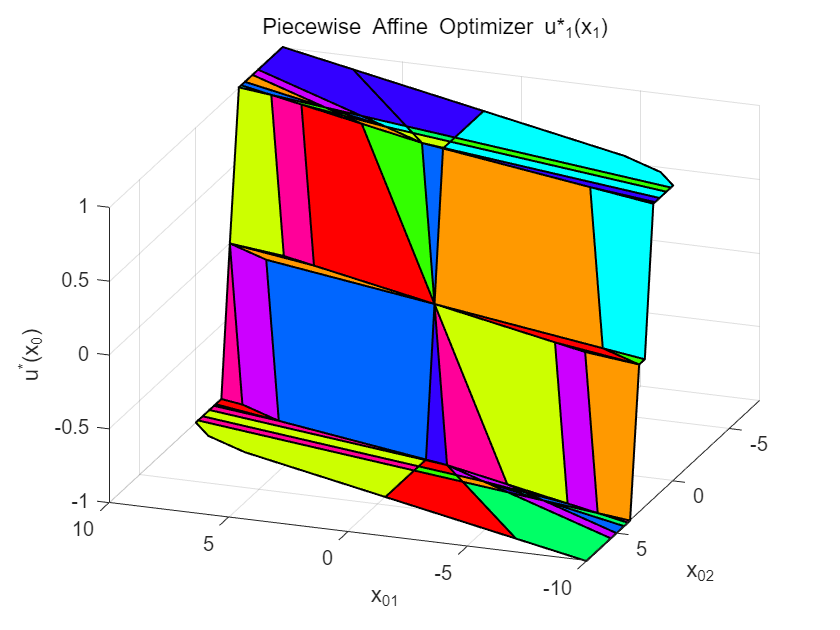

for i = 1:4
    figure;
    hold on
    title('Critical Region')
    xlabel('x_{01}')
    ylabel('x_{02}')
    solution(i).xopt.plot();
    figure;
    hold on
    xlabel('x_{01}')
    ylabel('x_{02}')
    zlabel('u^*(x_0)')
    title(['Piecewise Affine Optimizer u*_',num2str(4-i),'(x_',num2str(4-i),')'])
    solution(i).xopt.fplot('primal');
    view([-160 30]);
    figure;
    hold on
    xlabel('x_{01}')
    ylabel('x_{02}')
    zlabel('J^*(x_0)')
    title('Piecewise Affine Optimal Objective')
    solution(i).xopt.fplot('obj');
end